**IMU Simulation: Basic Signal Processing using the Welche Earle Method**

**Author: Michael Noyce**

Description

This program takes the data of the MPU6050 based on the **Simulatiuon_IMU_MPU_6050_Version_1** (run this first so that the variable are in the workspace) and performs basic signal processing. 

Current Program: Uses basic implementation of method derived from Kohout without statistical tests (not a problem currently as ideal input is known)

Future program updates: Implement several wave processing techniques

% Start of Program
% Run Simulation_IMU_MPU6050_Version_1 first to ensure the correct
% variables are in the workspace


**Preprocessing and filtering of time series **

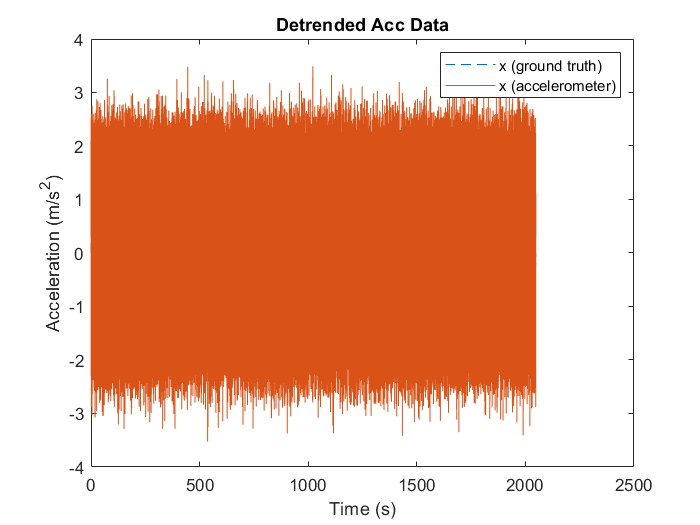


%Step 1: Detrend the time series
AccData_detrend = detrend(accData);

%Plot output of the detrended data
figure
plot(t, acc(:,1), '--', t, AccData_detrend(:,1))
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Detrended Acc Data')
legend('x (ground truth)', 'x (accelerometer)') 

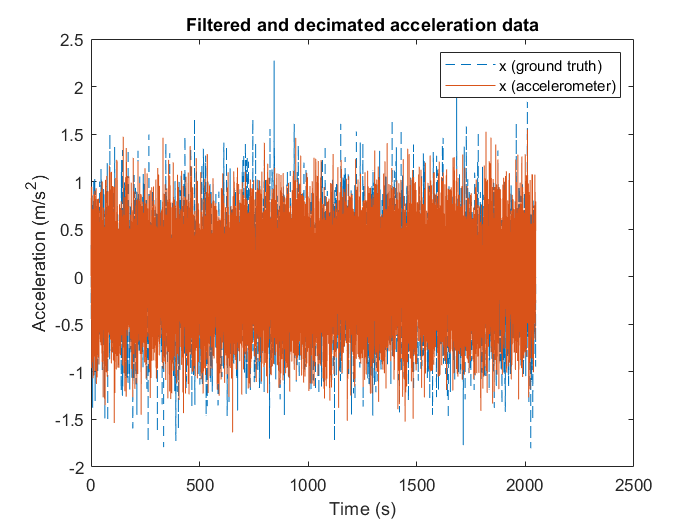



%Step 2: Oversample data
%Data is already oversampled (640Hz )
usample = 1; 
dsample = 1;
AccData_oversample = resample(AccData_detrend, usample, dsample);

%Step 3: Filter and Decimate Data 
fc_lpfilter_1 = 1;
fs_lpfilter_1 = 8;

[b,a] = butter(2,fc_lpfilter_1/(fs_lpfilter_1/2));
AccData_lp_1 = filter(b, a, AccData_oversample);
AccData_decimate_1 = downsample(AccData_lp_1, 80);

fc_lpfilter_2 = 0.5;
fs_lpfilter_2 = 2;

[b,a] = butter(2,fc_lpfilter_2/(fs_lpfilter_2/2));
AccData_lp_2 = filter(b, a, AccData_decimate_1);
AccData_decimate_2 = downsample(AccData_lp_2, 4);

AccData_Actual_Decimate = downsample(accData, 320);
t_decimate = downsample(t, 320);

%Plot output of the Oversampled and decimated data
figure
plot(t_decimate, AccData_Actual_Decimate(:,1), '--', t_decimate, AccData_decimate_2(:,1))
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Filtered and decimated acceleration data')
legend('x (ground truth)', 'x (accelerometer)') 

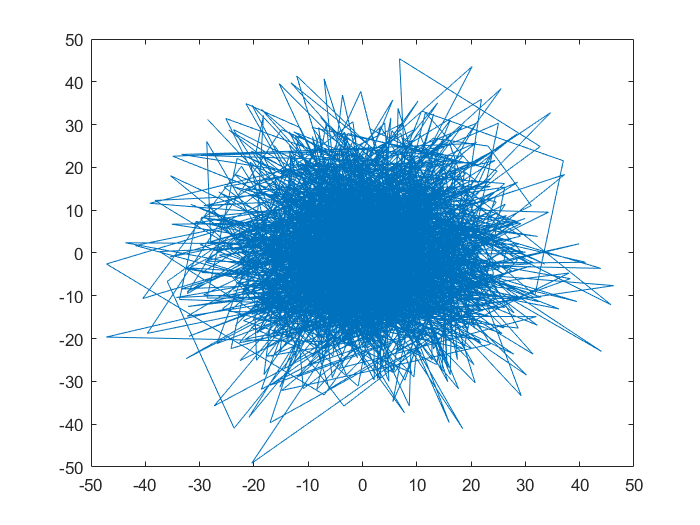


%Step 4: FFT Filter data to high pass filter data to prevent drift after
%double integration of acceleration

fft_Acc_LP_Dec=fft(AccData_decimate_2); % ffty is the fft of y
lfft=length(fft_Acc_LP_Dec); % Length of the FFT
fft_Acc_LP_Dec(lfft-2048:lfft)=0; % All frequencies between n and lfft-n in the fft are set to zero.

figure
plot(fftshift(fft_Acc_LP_Dec(:,1)));

**Frequency Analysis of data **

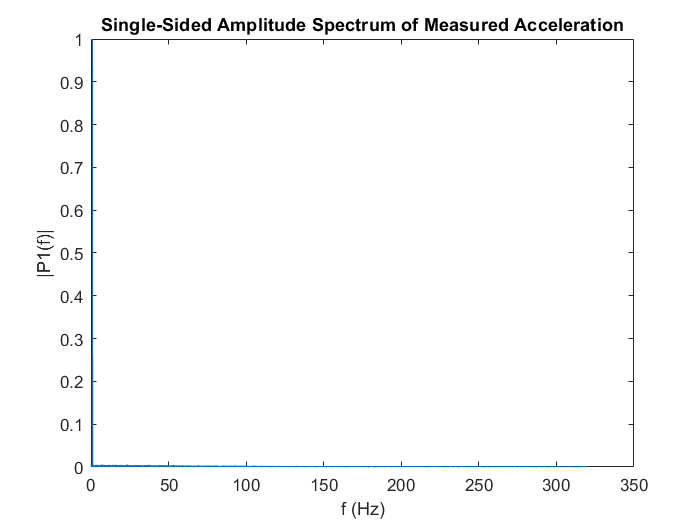


%FFT of raw time series
Y = fft(accData);

P2 = abs(Y/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;

plot(f, P1);
title('Single-Sided Amplitude Spectrum of Measured Acceleration')
xlabel('f (Hz)')
ylabel('|P1(f)|')

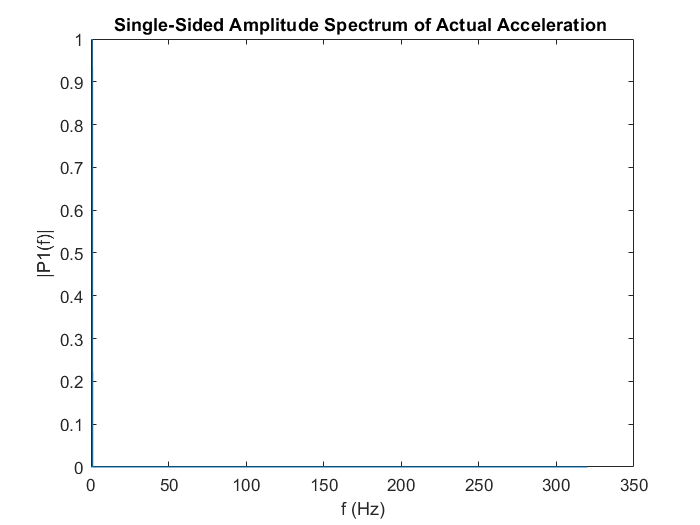


%FFT of original signal
acc(:,1) = 1*sin(2*pi*Fc*t);

Y = fft(acc(:,1));

P2 = abs(Y/N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;

plot(f, P1);
title('Single-Sided Amplitude Spectrum of Actual Acceleration ')
xlabel('f (Hz)')
ylabel('|P1(f)|')

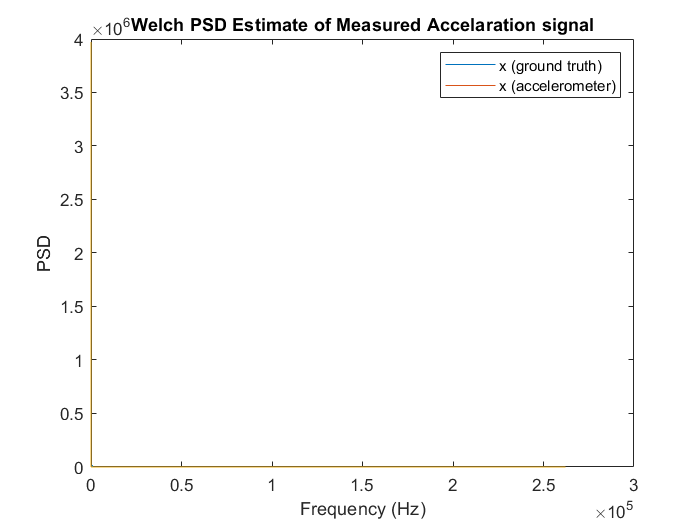


%pwelche of raw time series 
pxx = pwelch(accData);

figure
plot(pxx);
xlabel('Frequency (Hz)')
ylabel('PSD')
title('Welch PSD Estimate of Measured Accelaration signal')
legend('x (ground truth)', 'x (accelerometer)') 